Mp_dB = 7.2;
Mp = 10^(Mp_dB/20)

Mp = 2.2909

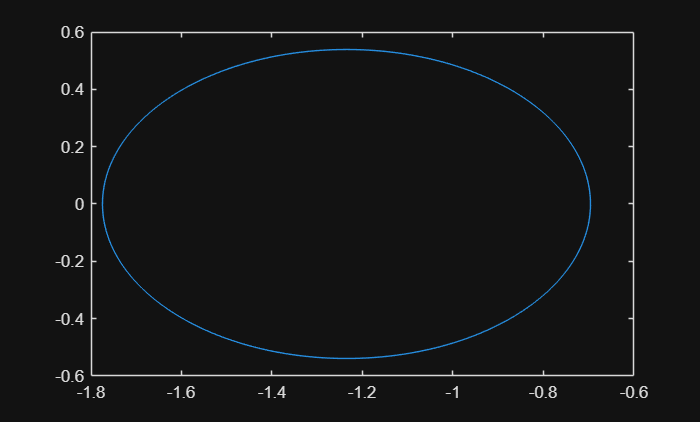

r = Mp/(Mp^2-1); x = -Mp^2/(Mp^2-1);
v = linspace(0,2*pi,200); plot(sin(v)*r+x,cos(v)*r)

Mp = 2.2909

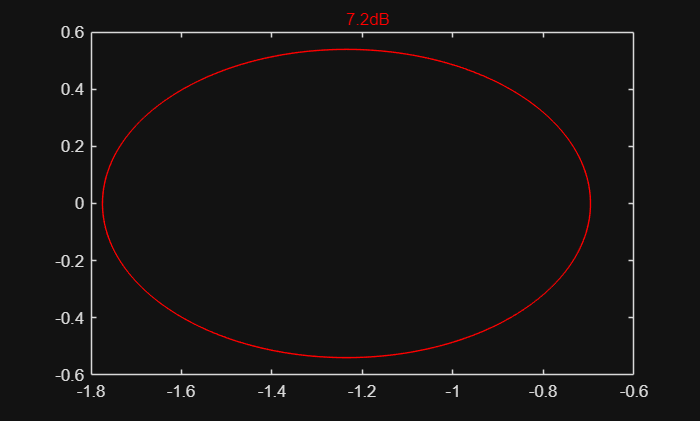

%test if the function works
CCM(7.2)

H_ol = zpk([], [0, -135], 9e4)


H_ol =
 
    90000
  ---------
  s (s+135)
 
Continuous-time zero/pole/gain model.


nyquist(H_ol); hold; CCM(7.2); hold

Current plot held


Mp = 2.2909

Current plot released


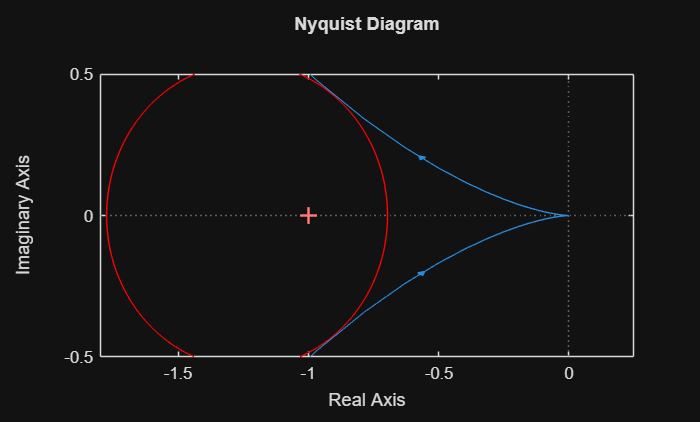

xlim([-1.8 0.25]);
ylim([-0.5 0.5]);

% axis([-3 0.25 -2 1]); shg my matlab doesn't run axis, i have to change it
% manualy

%different value for k
k=3; H_ol = zpk([], [0 -135], 9e4*k);
nyquist(H_ol); hold; CCM(11.8); hold

Current plot held


Mp = 3.8905

Current plot released


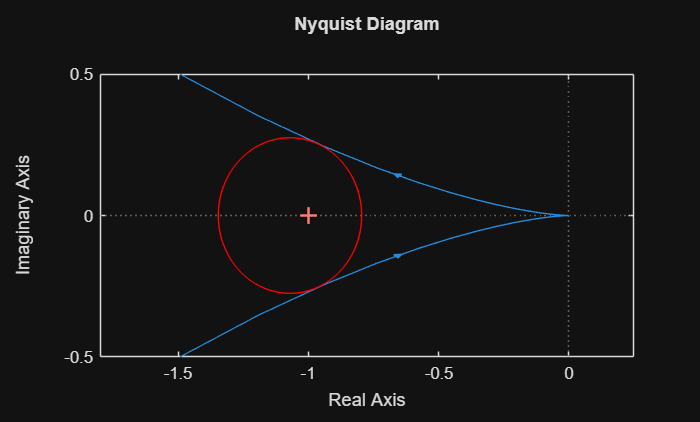

xlim([-1.8 0.25]);
ylim([-0.5 0.5]);

shg

% conclusion about the CL overshoot 11.8db -> (60%-67%)

% check the CL overshoot
H_cl = feedback(H_ol, 1)


H_cl =
 
         2.7e+05
  ---------------------
  (s^2 + 135s + 2.7e05)
 
Continuous-time zero/pole/gain model.


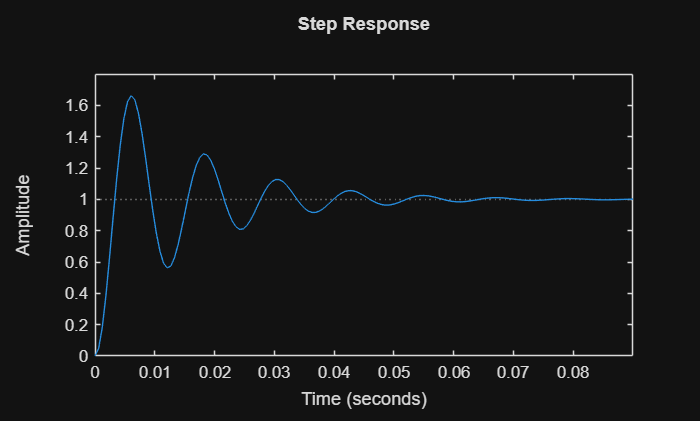

step(H_cl)

% when having time delay on the 
k=0.2; tm=0.0015; H_ol = zpk([], [0 -135], 9e4*k, 'iodelay', tm)


H_ol =
 
                     18000
  exp(-0.0015*s) * ---------
                   s (s+135)
 
Continuous-time zero/pole/gain model.


H_cl = feedback(H_ol, 1)


H_cl =
 
  A = 
             x1        x2
   x1         0         1
   x2  -1.8e+04      -135
 
  B = 
        u1
   x1    0
   x2  128
 
  C = 
          x1     x2
   y1  140.6      0
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.0015 
 
Continuous-time state-space model.


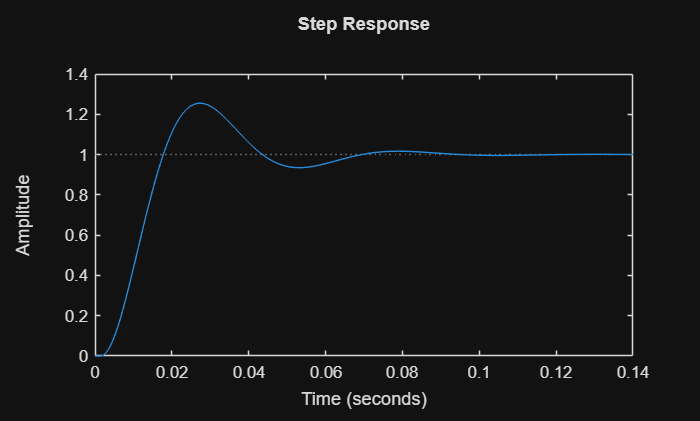

step(H_cl)

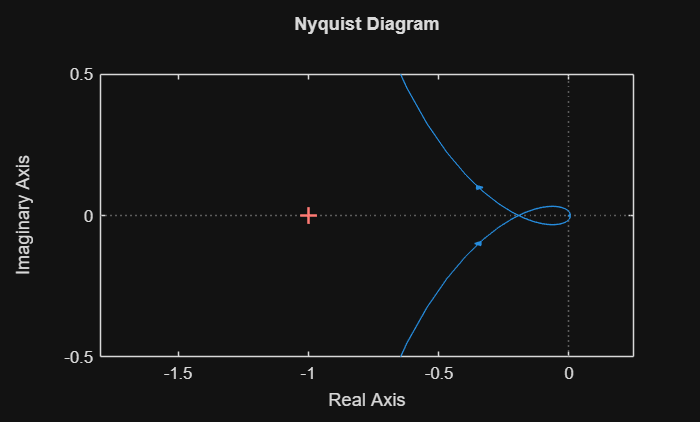

nyquist(H_ol)
xlim([-1.8 0.25]);
ylim([-0.5 0.5]);

% Homework: write a matlab script that connects the MP_dB from OL ND to the
% overshoot for the CL

type CCM.m


function [] = CCM(Mp_dB)
%Circle of Constant Magnitude

Mp = 10^(Mp_dB/20)
r = Mp/(Mp^2-1); x = -Mp^2/(Mp^2-1);
v = linspace(0,2*pi,200); plot(sin(v)*r+x,cos(v)*r, 'r');
text(x,r*1.2,[num2str(Mp_dB),'dB'], 'Color','r')
end
